clear
% Ln = [3 3.2 3.4 3.5 3.6 3.75 3.8 4 4.2 4.4 4.6 4.8 5];% values of Ln for which the code is running (Lm/Lr)
% Qe = (.1:.05:1);
% [~,columns] = size(Ln);
% [~,columns_1] = size(Qe);
fn =logspace(-1,1,350);% creating a logspace for the frequency 
A = fn.^2-1;

fsw_nom = 135e3;
Vout_min = 10.5;
Vout_max =15.5;
Vin_max = 450;
Vin_min =250;
Vout = 12;

Pout = 4000

Pout = 4000

n = 30

n = 30

Ro = Vout*Vout/Pout; % Rated ouput resistance
Re = 8*(n*n)*Ro/(pi*pi);
Mg_max = n*(Vout_max + .4)/((Vin_min)); 
Mg_min = n*(Vout_min)/((Vin_max));

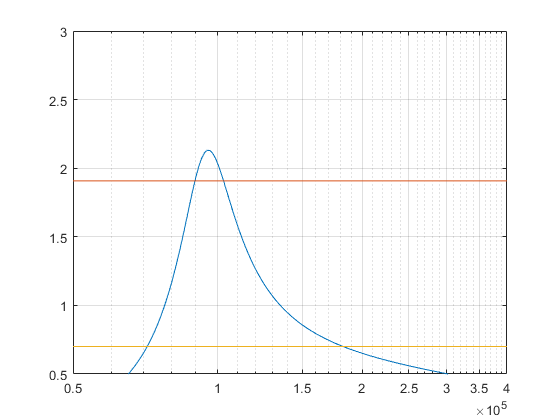


% %verification of the Chosen values of Ln,Qe to measure the frequency range
%of the switching 

%maximum Qe required would be at 10.5 and 4000W
 Ln_chosen = 1.2;
 Qe_chosen =.62;
 Qe_noload = .0;
%  C_r = 272.57e-09
%  L_r = 6.4537e-06
%  L_m = Ln_chosen*L_r
 
 Qe_full_load = Qe_chosen;
 i =1;
 
% finding the the  minimum frequency point 

num = Ln_chosen*fn.^2;
% ,.175,.14,.125,.1,.075,.05,.025,Qe_noload
for Qe = Qe_full_load
    denom_real = (Ln_chosen+1)*fn.^2 - 1;
    B = fn * Qe *Ln_chosen;
    denom_imag = times(A,B);
    Mg = num./(denom_real + 1i*denom_imag);
    Mg = abs(Mg); % have to save these valuesto find the intersection
    semilogx(fn*fsw_nom,Mg)
   
    hold on ;

end
grid on ;
ylim([.5 3]);
semilogy([.5e5 4e5],[Mg_max Mg_max]);
semilogy([.5e5 4e5],[Mg_min Mg_min]);

% yline(Mg_min); 


yi = Mg_max;
[~,idx] = max(Mg);
fsw_min = interp1(Mg(idx:end),fn(idx:end),yi)*fsw_nom 

fsw_min = 1.0285e+05

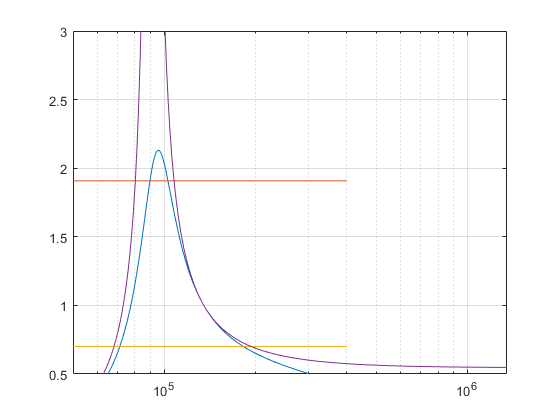


%finding the maximum frequency point 



for Qe = Qe_noload
    denom_real = (Ln_chosen+1)*fn.^2 - 1;
    B = fn * Qe *Ln_chosen;
    denom_imag = times(A,B);
    Mg = num./(denom_real + 1i*denom_imag);
    Mg = abs(Mg); % have to save these valuesto find the intersection
    semilogx(fn*fsw_nom,Mg)
    hold on ;
end
grid on ;
ylim([.5 3]);

% yline(Mg_max);
% yline(Mg_min); 

yi = Mg_min;
yi1 = 2;
yi2 = 1.5;
[~,idx] = max(Mg);
fsw_max = interp1(Mg(idx:end),fn(idx:end),yi)*fsw_nom

fsw_max = 1.9371e+05



fspan = fsw_max-fsw_min

fspan = 9.0866e+04

fsw_2 = interp1(Mg(idx:end),fn(idx:end),yi1)*fsw_nom

fsw_2 = 1.0675e+05

fsw_1_5 = interp1(Mg(idx:end),fn(idx:end),yi2)*fsw_nom

fsw_1_5 = 1.1411e+05

freq_diff = fsw_1_5 - fsw_2

freq_diff = 7.3604e+03

sen = .5/(freq_diff);
vol_var = sen*(300/n)*100

vol_var = 0.0679


Cr = 1/(2*pi*Re*fsw_nom*Qe_chosen)

Cr = 7.2403e-08

Lr = 1/(((2*pi*fsw_nom)^2)*Cr)

Lr = 1.9196e-05

Lm = Lr*Ln_chosen

Lm = 2.3035e-05


% Vout = 12.5;
% Vin = 250;
% Pout = 4000;
% n = 33;
% L_r = 6.4537e-6;
% C_r = 272.57e-9;
% L_m = 32.268e-6;% we would have to check if we get ZVS at all possible values then if so then it would be good since it is also decreasing the conduction loss 
% Ln_chosen = L_m/L_r;
% 
% Ro = Vout*Vout/Pout;
% Re = 8*(n*n)*Ro/(pi*pi);
% Qe_load = sqrt(L_r/C_r)/(Re);
% m = L_m/L_r;
% 
% for Qe = Qe_load
%     denom_real = (Ln_chosen+1)*fn.^2 - 1;
%     B = fn * Qe *Ln_chosen;
%     denom_imag = times(A,B);
%     Mg = num./(denom_real + 1i*denom_imag);
%     Mg = abs(Mg); % have to save these valuesto find the intersection
%     semilogx(fn,Mg)
%     hold on ;
% end
% grid on ;
% ylim([.5 3]);
% yline(Mg_max);
% yline(Mg_min); 
% Mg_req = (Vout + 1.4)*n/Vin;
% 
% yi = Mg_req;
% [~,idx] = max(Mg);
% fsw_req = interp1(Mg(idx:end),fn(idx:end),yi)*fsw_nom
% 


% B = 1/(4*fsw_req*sqrt(L_r*C_r))
% func = @(A) ((-1/n)*(sin(A-B))/((B*cos(B)/m)+sin(B)) - Vout/Vin);
% A =0 ;
% root = fzero (func,A)
% A_interval = [-1 5]
% figure 
% 
% fplot(func,A_interval)
% A = 2.75;
% t1 = A*sqrt(L_r*C_r)
% T = ((1/(2*fsw_req)) - t1)/(sqrt((L_m + L_r)*C_r))
% func = @(A) ((((2*m)/(A*n))/ ((2*m/A) + cot(A/2) - (sqrt(m+1)*tan(T/2)))) - Vout/Vin);
% root = fzero(func,A)
% t1 = root*sqrt(L_r*C_r)
% T = ((1/(2*fsw_req)) - t1)/(sqrt((L_m + L_r)*C_r))
% A_interval = [0 10];
% figure 
% fplot(func,A_interval)

## Percentage variation in the Resonant Parameters

% percentvar = -5;
% L_r_var = L_r * (1 + (percentvar/100))
% C_r_var = C_r
% L_m_var = L_m
% new_Ln = L_m_var/L_r_var
% new_f_series =1/(2*pi*sqrt(L_r_var * C_r_var)) 
% new_Qe = 1/(2*pi*C_r_var*new_f_series*Re)

## Variation in frequency limits

%  Ln_chosen = new_Ln
%  Qe_chosen = new_Qe
%  Qe_noload = .01;
%  fsw_nom = new_f_series
%  
%  Qe_full_load = Qe_chosen;
%  i =1;
%  
% % finding the the  minimum frequency point 
%  figure;
% num = Ln_chosen*fn.^2;
% for Qe = Qe_full_load
%     denom_real = (Ln_chosen+1)*fn.^2 - 1;
%     B = fn * Qe *Ln_chosen;
%     denom_imag = times(A,B);
%     Mg = num./(denom_real + 1i*denom_imag);
%     Mg = abs(Mg); % have to save these valuesto find the intersection
%     semilogx(fn,Mg)
%     hold on ;
% 
% end
% grid on ;
% ylim([.5 3]);
% yline(Mg_max);
% yline(Mg_min); 
% 
% 
% yi = Mg_max;
% [~,idx] = max(Mg);
% fsw_min = interp1(Mg(idx:end),fn(idx:end),yi)*fsw_nom 
% 
% 
% %finding the maximum frequency point 
% 
% 
% for Qe = Qe_noload
%     denom_real = (Ln_chosen+1)*fn.^2 - 1;
%     B = fn * Qe *Ln_chosen;
%     denom_imag = times(A,B);
%     Mg = num./(denom_real + 1i*denom_imag);
%     Mg = abs(Mg); % have to save these valuesto find the intersection
%     semilogx(fn,Mg)
%     hold on ;
% end
% 
% 
% yi = Mg_min;
% [~,idx] = max(Mg);
% fsw_max = interp1(Mg(idx:end),fn(idx:end),yi)*fsw_nom
